#### 数据加载

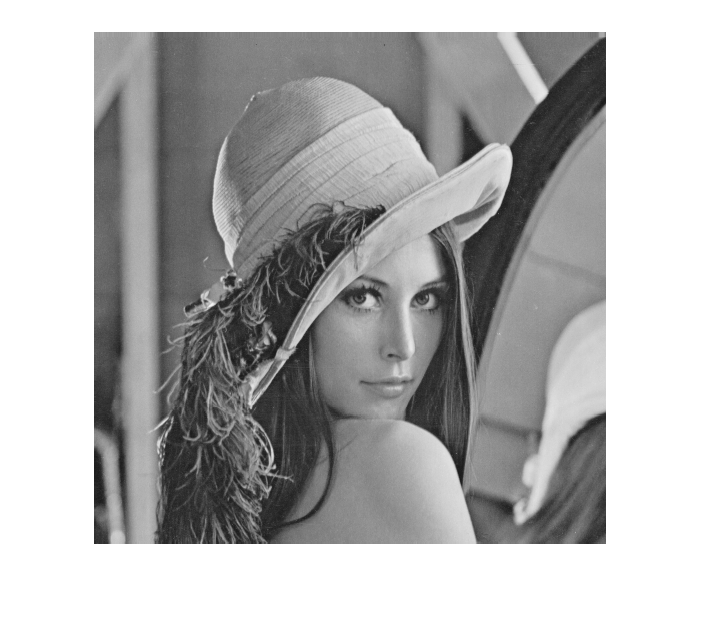

img = imread('Lena.bmp');
imshow(img);

#### 图像分割

% 图像分割为8x8的块
[segs, h, w] = imseg(img);
dsegs = segs - 128;

#### 实现DCT/IDCT

% DCT变换矩阵
A = 1/2.*cos((0:7)'.*(1:2:15)*pi/(2*8)).*[ones(1,8)/sqrt(2);ones(7,8)];
% 对图像做二维DCT变换
tseg = A*dsegs(:,:,1)*A';
% 与Matlab自带的DCT变换比较
tsegcmp = dct2(dsegs(:,:,1));
max(tseg-tsegcmp, [], 'all')

ans = 7.8382e-14

% DCT反变换
rtseg = A'*tseg*A;
max(dsegs(:,:,1)-rtseg, [], 'all')

ans = 4.9738e-14

% 与Matlab自带的IDCT变换比较
rtsegcmp = idct2(tsegcmp);
max(dsegs(:,:,1)-rtsegcmp, [], 'all')

ans = 1.7764e-14

#### 对片段做DCT变换

tsegs = zeros(8, 8, size(dsegs, 3));
for i=1:size(segs, 3)
    tsegs(:,:,i) = A*dsegs(:,:,i)*A';
end

#### 量化

QF = 50;
Q = getQ(QF);
qtsegs = zeros(8, 8, size(dsegs, 3), 'int16');
for i=1:size(segs, 3)
    qtsegs(:,:,i) = round(tsegs(:,:,i)./Q);
end

#### Zipzag读取

zzs = zeros(64, size(qtsegs, 3), 'int16');
for i=1:size(segs, 3)
    zzs(:,i) = zipzag(qtsegs(:,:,i));
end

#### 熵编码

PRED = 0;
code = []; clen = 0;
for i = 1:size(zzs, 2)
    % 对直流系数编码
    diff = zzs(1, i) - PRED;
    PRED = zzs(1, i);
    [c, len] = DCenc(diff);
    code = [code c];
    clen = clen + len;
    % 对交流系数编码
    [c, len] = ACenc(zzs(2:end, i));
    code = [code c];
    clen = clen + len;
end

#### 统计压缩率(忽略文件头)

% 熵编码后大小(字节)
compressed_size = varconvert(clen)/8;
% 压缩前图像大小(字节)
origin_size = h * w;
eta = compressed_size / origin_size

eta = 0.1587

#### 反量化

rqtsegs = zeros(8, 8, size(dsegs, 3));
for i=1:size(segs, 3)
    rqtsegs(:,:,i) = double(qtsegs(:,:,i)).*Q;
end

#### IDCT变换

rdsegs = zeros(8, 8, size(dsegs, 3));
for i=1:size(segs, 3)
    rdsegs(:,:,i) = A'*rqtsegs(:,:,i)*A;
end

#### 恢复图像

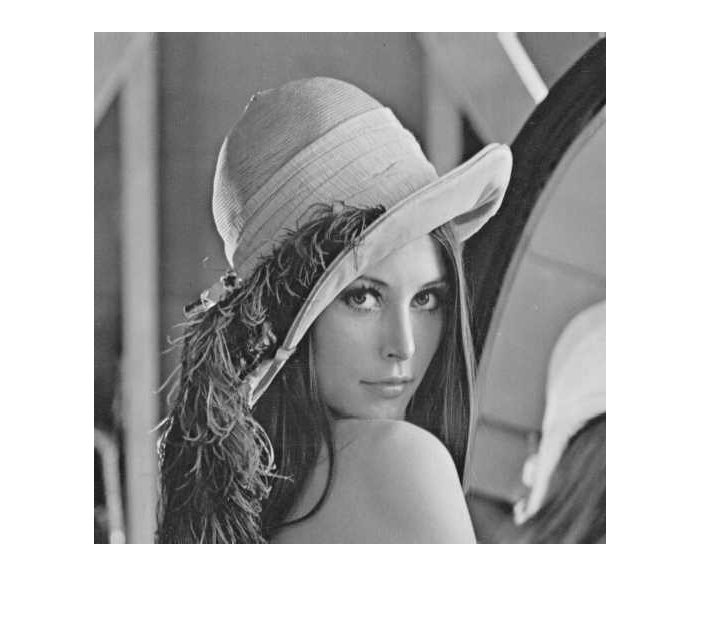

rsegs = rdsegs + 128;
rimg = imrseg(rsegs, h, w);
imshow(rimg);

#### PSNR

psnr(rimg, img)

ans = 35.7846